N=5000

N = 5000

X_train=[-N+1:N]

X_train =        -4999       -4998       -4997       -4996       -4995       -4994       -4993       -4992       -4991       -4990       -4989       -4988       -4987       -4986       -4985       -4984       -4983       -4982       -4981       -4980       -4979       -4978       -4977       -4976       -4975       -4974       -4973       -4972       -4971       -4970       -4969       -4968       -4967       -4966       -4965       -4964       -4963       -4962       -4961       -4960       -4959       -4958       -4957       -4956       -4955       -4954       -4953       -4952       -4951       -4950


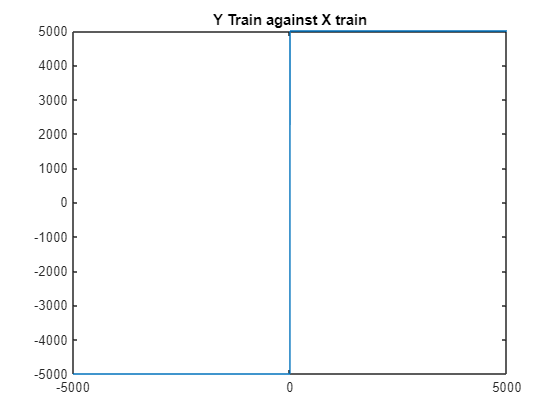

Y_train=[];
Y_train(X_train<0) = -N;
Y_train(X_train>=0) = N;
plot(X_train,Y_train)
    title("Y Train against X train")

net=feedforwardnet();
net.trainParam.showWindow = false;
net=train(net,X_train,Y_train)

net =

    Neural Network
 
              name: 'Feed-Forward Neural Network'
          userdata: (your custom info)
 
    dimensions:
 
         numInputs: 1
         numLayers: 2
        numOutputs: 1
    numInputDelays: 0
    numLayerDelays: 0
 numFeedbackDelays: 0
 numWeightElements: 31
        sampleTime: 1
 
    connections:
 
       biasConnect: [1; 1]
      inputConn

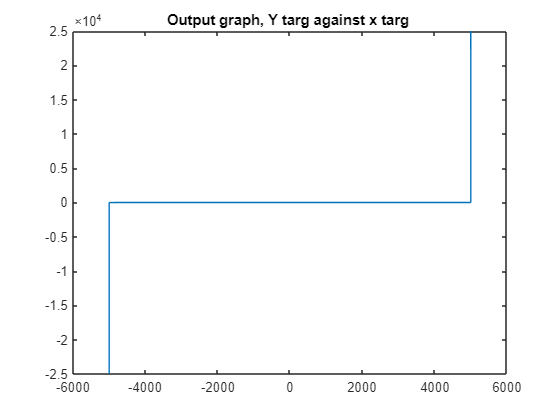

x_targ=[-5*N:5*N];
y_targ=net(x_targ);
plot(y_targ, x_targ)
title("Output graph, Y targ against x targ ")